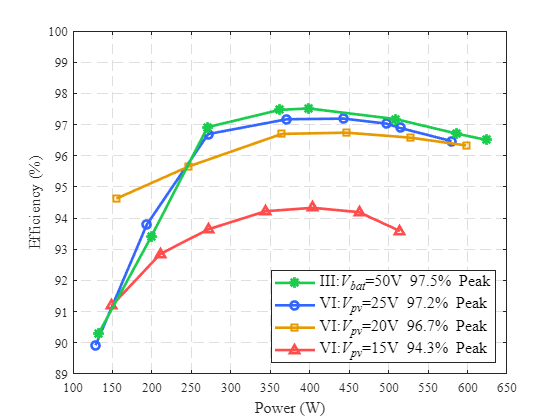

% 定义光伏端口的功率和效率数据
% 对应25V的光伏端口数据
power_25V = [579.756, 514.424, 496.956, 443.251, 370.932,271.33,193.479,128.588];
efficiency_25V = [96.47, 96.89, 97.03, 97.19, 97.17,96.695,93.788,89.92
];

% 对应20V的光伏端口数据
power_20V = [598.216, 527.41, 446.833, 364.668,247,154.847];
efficiency_20V = [96.33, 96.58, 96.74, 96.7,95.66,94.624];

% 对应15V的光伏端口数据
power_15V = [514.306,462.454, 403.854, 343.895,271.37,210.571,148.83];
efficiency_15V = [93.5846,94.19, 94.33, 94.22,93.639,92.848,91.187];

% 正向数据（电池端口到DC bus）
power_forward = [623.5, 585.4, 509, 398.795, 361.7,270.456,199.47,132.246];
efficiency_forward = [96.509, 96.714, 97.174, 97.516, 97.470,96.915,93.42,90.29];

% 创建一个新的图形窗口
figure;

% 绘制25V光伏端口数据
h1 = plot(power_25V, efficiency_25V, '-o', 'DisplayName', 'Mode VI: V_{pv}=25V', 'LineWidth', 2, 'MarkerSize', 6, 'Color', [0.2, 0.4, 1]); % 使用更柔和的蓝色

hold on;

% 绘制20V光伏端口数据
h2 = plot(power_20V, efficiency_20V, '-s', 'DisplayName', 'Mode VI: V_{pv}=20V', 'LineWidth', 2, 'MarkerSize', 6, 'Color', [0.9, 0.6, 0]); % 使用更柔和的绿色

% 绘制15V光伏端口数据
h3 = plot(power_15V, efficiency_15V, '-^', 'DisplayName', 'Mode VI: V_{pv}=15V', 'LineWidth', 2, 'MarkerSize', 6, 'Color', [1, 0.3, 0.3]); % 使用更柔和的红色

% 绘制正向数据，符号改为有连线的五角星
h4 = plot(power_forward, efficiency_forward, '-*', 'DisplayName', 'Mode III: V_{bat}=50V', 'LineWidth', 2, 'MarkerSize', 8, 'Color', [0.1, 0.8, 0.3]); % 使用有连线的五角星

% 设置坐标轴标签
xlabel('Power (W)', 'FontSize', 12, 'FontName', 'Times New Roman');
ylabel('Efficiency (%)', 'FontSize', 12, 'FontName', 'Times New Roman');

% 设置坐标轴范围
xlim([100, 650]); % 将横坐标范围从300开始
ylim([89, 100]); % 根据效率范围，设定纵坐标范围

% 添加网格
grid on;
set(gca, 'GridLineStyle', '--'); % 设置网格线为虚线

% 添加图例并指定顺序，同时设置位置为左上角
legend([h4, h1, h2, h3], {'III:\it{V_{bat}}\rm=50V 97.5% Peak', 'VI:\it{V_{pv}}\rm=25V 97.2% Peak', 'VI:\it{V_{pv}}\rm=20V 96.7% Peak', 'VI:\it{V_{pv}}\rm=15V 94.3% Peak'}, 'Location', 'southeast', 'FontSize', 12, 'FontName', 'Times New Roman');

% 设置字体为新罗马字体
set(gca, 'FontName', 'Times New Roman');

% 显示图形
hold off;


% 导出为 PDF 格式，设置输出尺寸
%exportgraphics(gcf, 'Efficiency of TPC.pdf', 'ContentType', 'image', 'BackgroundColor', 'none');